# Diseño controlador H-infinito / Sensibilidad Mixta

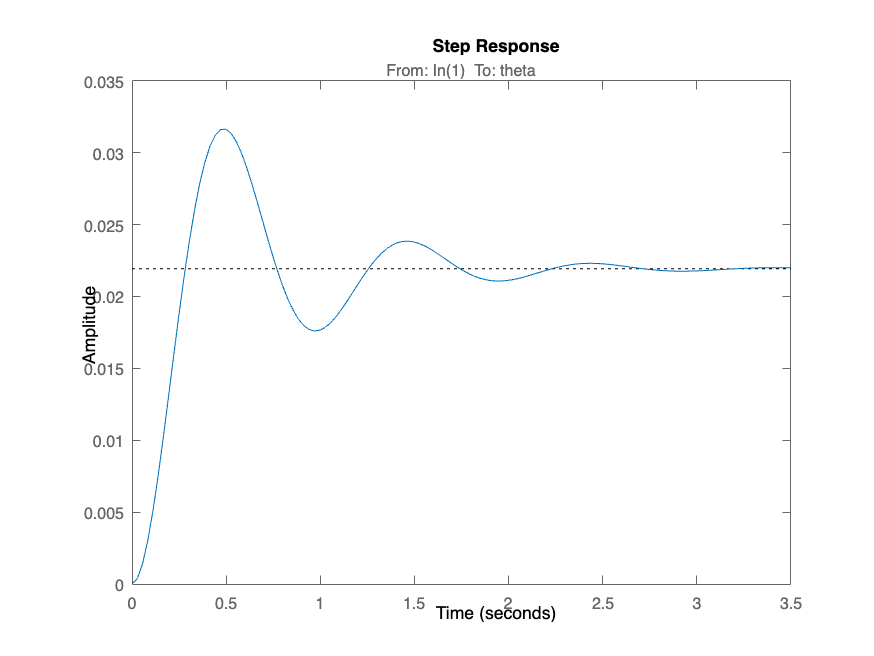

step(Gss); %% Lazo abierto de planta

Definición de las prestaciones: 

- Seguimiento de Referencia Perfecto (ep = 0) 

- Accion de Control entre (0 < u < 100) [ % PWM ]

- Menor tiempo posible (Mayor ancho de banda) 

- Rechazo a perturbaciones 

Definición de señales 

- ***El controlador recibe error en radianes y lo convierte a Porcentaje de PWM % ***

## Definición de Filtros de Ponderación

- $S$ -> Sensibilidad del sistema 

- KS -> Accion de control 

- T -> Sensibilidad Complementaria 


$$T+S=1$$
 

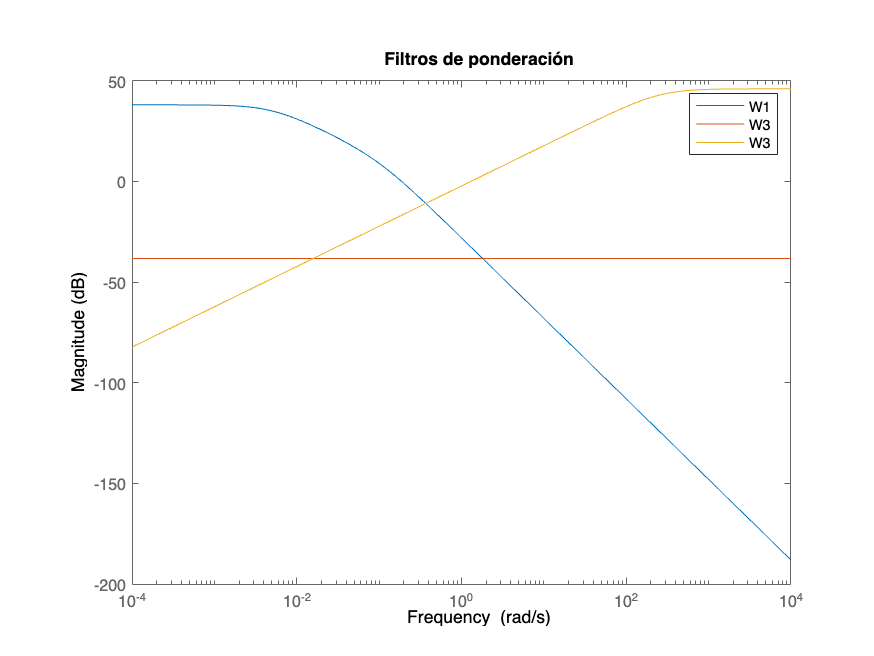

% Definición de filtros 

s = tf('s'); 
W1 = makeweight(80, 0.4, 1e-6) * 1/(s/0.1 + 1);       %% Sensibilidad 
W2 = ss(1/50 * deg2rad(35));      %% Acción de Control  
W3 = makeweight(1e-6,1.3, 200);      %% Sensibilidad Complementaria
% Grafica de filtros 
bodemag(W1, W2, W3);
legend("W1", "W3", "W3"); 
title("Filtros de ponderación"); 

[K, CL, GAM] = mixsyn(Gss, W1, W2, W3); % Solucion problema H-infinito
GAM

GAM = 0.6243

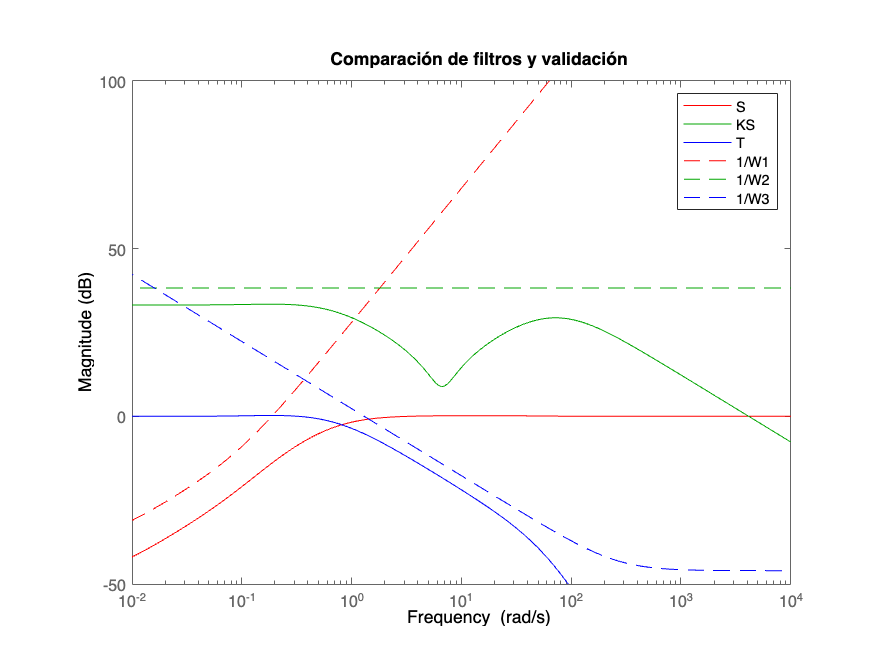

% Validación de filtros y H infinito 
S = feedback(1, K * G);
KS = K * S; 
T = 1 - S; 

% Graficas 
bodemag(S, "r-", KS, "g-", T, "b-"); hold on; 
bodemag(1/W1, "r--", 1/W2, "g--", 1/W3, 'b--'); hold off;
title("Comparación de filtros y validación"); 
legend("S", "KS", "T", "1/W1", "1/W2", "1/W3")
axis([1e-2 10e3, -50, 100]); 

## Respuesta de lazo cerrado

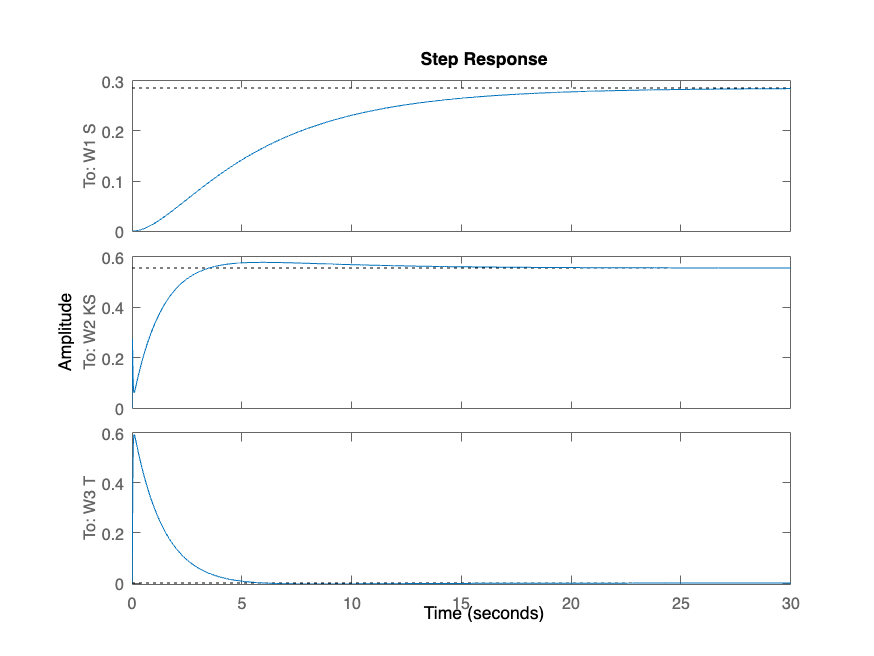

% MAtriz de transferencia aumentada
CL.OutputName = {'W1 S', 'W2 KS', 'W3 T'}; 
step(CL); 

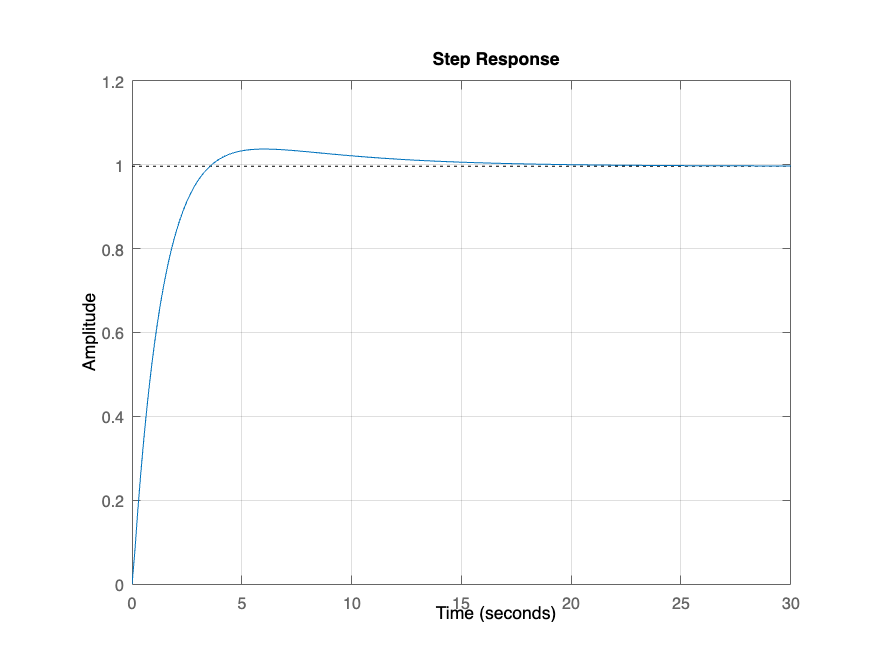

OL = series(K, G); 
T = feedback(OL, 1); 
U = feedback(K, G); 


%% Respuesta directa 
step(T); 
bandwidth(T); grid on; 

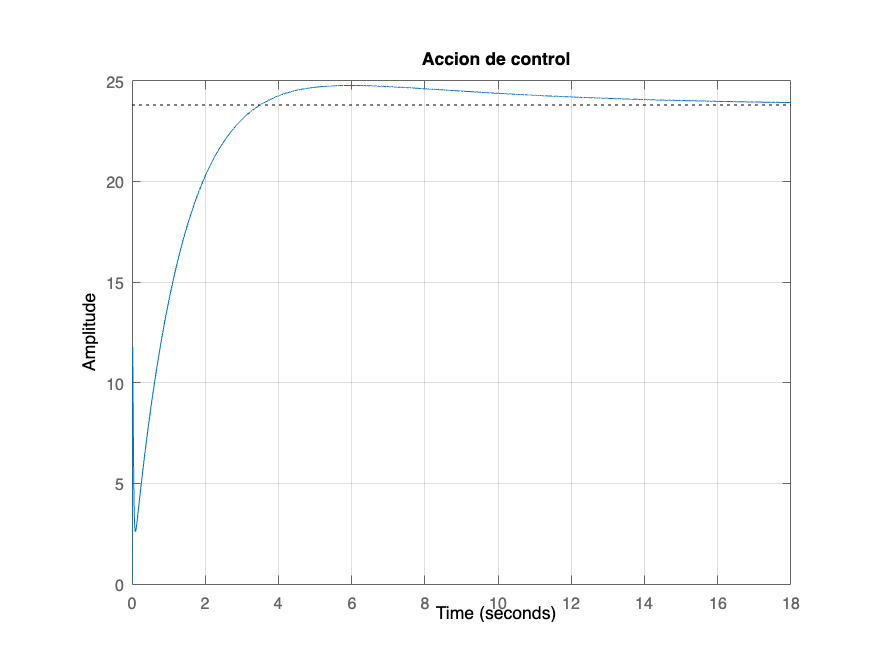


% Respuesta de accion de control
step(pi/6 * U);  
title("Accion de control"); grid on; 

% Función de transferencia; 
size(K); 

State-space model with 1 outputs, 1 inputs, and 5 states.


Ktf = tf(K); 

## Implementacion en arduino

Ts = 2.5e-3;  % Tiempo de muestreo

HinfDiscrete = c2d(K, Ts, 'tustin')

HinfDiscrete =
 
  A = 
               x1          x2          x3          x4          x5
   x1           1   0.0004999   4.839e-18   1.377e-16  -5.531e-18
   x2   8.106e-17      0.9998   2.348e-17  -1.174e-17   1.954e-18
   x3    0.008718     0.01031        0.51      0.4793   0.0005118
   x4      0.0361     0.04267    0.002148      0.9846    0.002119
   x5       28.88       34.14       1.718      -12.34      0.6954
 
  B = 
              u1
   x1  1.562e-07
   x2  0.0006249
   x3  3.221e-06
   x4  1.334e-05
   x5    0.01067
 
  C = 
              x1         x2         x3         x4         x5
   y1   1.19e+04  1.407e+04      708.3      -5041     -122.1
 
  D = 
          u1
   y1  4.398
 
Sample time: 0.0025 seconds
Discrete-time state-space model.



save("controllers/Hinf/Hinf.mat", "HinfDiscrete"); 

Error using save
Cannot create 'Hinf.mat' because 'controllers/Hinf' does not exist.

## Revision en discreto

Gdiscrete = c2d(Gss, Ts, 'tustin'); 

Tdiscrete = feedback(series(HinfDiscrete, Gdiscrete), 1); 
step(Tdiscrete)

## Simulación Sistema No Lineal

DirectCMD = 40;
results = sim("hinfNL.slx",50); 

t = results.tout; % tiempo de simulación    

% Estados del sistema
theta = results.theta.Data;
ref = results.Ref.Data;

figure()
plot(t,ref,'-', 'LineWidth',1); 
hold on; 
plot(t,theta);
hold off
xlabel('Tiempo [s]');
ylabel('theta [°]');
ylim([60 120])
legend('Referencia', 'Ángulo','Location','best');